# **Análisis del Tráfico Telefónico Rural en el Perú: 2006-2016**

Este análisis de tráfico telefónico rural toma como base los datos oficiales publicados e

n la página web de indicadores estadisticos del OSIPTEL.

- [https://www.osiptel.gob.pe/documentos/8-indicadores-de-servicios-de-comunicaciones-rurales](https://www.osiptel.gob.pe/documentos/8-indicadores-de-servicios-de-comunicaciones-rurales)

### Limpiando el espacio de trabajo

clear all

## A. Descarga de datos de tráfico telefónico rural

Esta información es de acceso público y está disponible para ser descargar de la página web de indicadores estadisticos del OSIPTEL.

% Fijamos url de origen para la descargar datos de trafico
url = ['https://www.osiptel.gob.pe/repositorioaps/data/1/1/1/par/'...
    '84-trafico-anual-saliente-por-departamento-y-empr/'...
    '8.4_Trafico_anual_saliente_por_departamento.xlsx'];
% Fijamos ruta de destino local para guardar datos de trafico
filename = ['C:\Users\huber\Documents\git\telecom\rural\data\'...
    '8.4_Trafico_anual_saliente_por_departamento.xlsx'];
outfilename = websave(filename,url)

outfilename = 'C:\Users\huber\Documents\git\telecom\rural\data\8.4_Trafico_anual_saliente_por_departamento.xlsx'

## B. Trafico anual saliente en minutos (T)

Esta información, la recuperamos del archivo descargado en el paso anterior(A) el cual tiene datos de trafico saliente en minutos en un periodo de 10 años (empezando el 2006).

% Configuramos la opcion lectura de hasta 13 variables (una variable por columna)
opts = spreadsheetImportOptions("NumVariables", 13);

% Configuramos el nombre de la pagina y el rango de datos (para recuperar los datos)
opts.Sheet = "Trafico Saliente";
opts.DataRange = "A3:M32";

% Importamos los datos de trafico rural en una variable temporal
tmp = readtable(filename, opts, "UseExcel", false);
% Quitamos la columna 2, que esta vacia en la variable temporal
tmp = removevars(tmp, 2);

% Guardamos información solo de trafico, quitamos informacion adicional
trafico = tmp(3:27,1:12);

% Guardamos información adicional de trafico
info{1} = string(table2cell(tmp(1,1)));
info{2} = string(table2cell(tmp(29,1)));
info{3} = string(table2cell(tmp(30,1)));

% Copiamos la fila 2, de la tabla temporal hacia  las cabeceras de la tabla trafico
trafico.Properties.VariableNames=table2cell(tmp(2,:));

% Invertimos la tabla trafico, en base a departamentos
T = rows2vars(trafico,"VariableNamesSource","Departamento");

% Cambiamos el valor de la primera cabecera hacia "Año"
T.Properties.VariableNames(1)="Año";

% Cambiamos el tipo de string a double para los valores de trafico
for var=T.Properties.VariableNames(2:26)
    var=string(var);
    T.(var)=str2double(T.(var));
end

disp(T)

      Año        AMAZONAS       ANCASH       APURIMAC      AREQUIPA      AYACUCHO     CAJAMARCA       CUSCO       HUANCAVELICA     HUANUCO         ICA          JUNIN       LALIBERTAD    LAMBAYEQUE       LIMA         LORETO      MADREDEDIOS     MOQUEGUA       PASCO         PIURA          PUNO       SANMARTIN       TACNA         TUMBES       UCAYALI      TotalPeru 
    ________    __________    __________    __________    __________    __________    

## C. Volumen de tráfico telefónico rural total en minutos

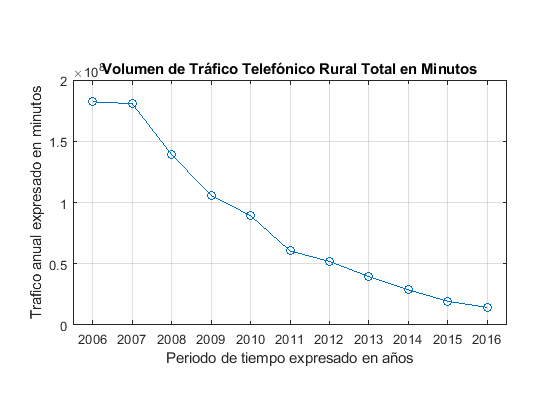

% Cambiamos la columna Año al tipo categoria
T.("Año") = categorical(T.("Año"));

% Graficamos el tráfico total por año
figure
plot(T.("Año"),T.TotalPeru,'-o')
grid on
pbaspect([16 9 1])
title('Volumen de Tráfico Telefónico Rural Total en Minutos')
xlabel('Periodo de tiempo expresado en años')
ylabel('Trafico anual expresado en minutos')

% Mostramos la descripcion de los datos
fprintf('%s\n%s\n%s',info{:})

Cuadro 8.4 Tráfico anual Saliente de teléfonos públicos rurales por departamento *
(*)  Información anual del tráfico expresado en minutos de los Teléfonos Públicos  Rurales de Telefónica del Perú S.A.A, Gilat to Home S.A., Rural Telecom S.A.C. y Winner Systems S.A.C.
No se consideraron los tráficos generados por los teléfonos públicos del proyecto Banda Ancha para localidades Aisladas-BAS de Telefónica del Perú S.A.A.

## **D. Función de distribución de probabilidad para la duración promedio del tiempo de servicio**

El numero prome dio de arribo lamb y mu el intervalo de tiempo promedio entre dos arribos de llambadas. Es decir, mu=10 para un intervalo promedio de llambadas de 6 minutos.

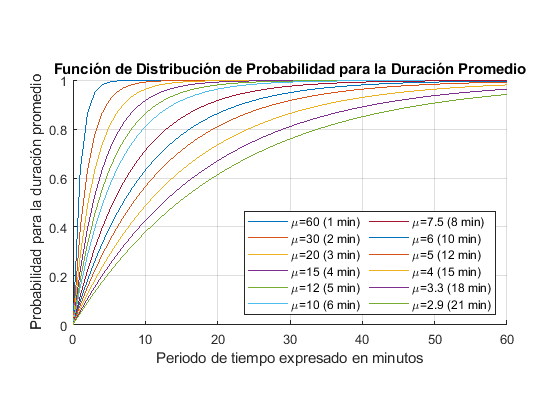

% Tiempo de servicio en minutos
tsmin=horzcat([1:5],[6:2:12],[15:3:21]);
% Convertimos tiempo en horas
ts=tsmin/60;
% Calculambos la tasa promedio de duración
mu=ts.^-1;
% Definimos el intervalo de tiempo de observación en minutos
tmin=[0:1:60];
% Convertimos el tiempo en minutos en horas
t=tmin/60;
% Configuramos la figura  
figure
hold on
% Graficamos para cada tasa de duración
for i=1:length(mu)
  
  p=1-mu(i).^-1*exppdf(t,mu(i).^-1);  
  %p=1-exp(1).^(-mu(i)*t); % equivalente
  plot(tmin,p)
  % Construimos data para la leyenda
  data{i}=['\mu='...
      num2str(mu(i),2)...
      ' ('...
      num2str(tsmin(i),2)...
      ' min)'];
end
% Configuramos la leyenda del grafico
legend(data,'Location','southeast','NumColumns',2)
% Activamos la grilla
grid on
% Configuramos la relación de aspecto del grafico
pbaspect([16 9 1])
% Configuramos los detalles del grafico
title('Función de Distribución de Probabilidad para la Duración Promedio')
xlabel('Periodo de tiempo expresado en minutos')
ylabel('Probabilidad para la duración promedio')

## **E. Función de distribución de probabilidad para el promedio de arribo de llamadas**

Esta definida por una distribucion del tipo poisson

% Consideramos la tasa de duración de llambada mu=10. Es decir, el tiempo
% promedio de servicio 6 minutos
ts=6;
mu=ts^-1;

% Convert categorical to double
anios=str2double(string(T.("Año")));
amins=365*ones(1,length(anios));
% Calculamos los años bisiestos
for i=[1:length(anios)]
    anio=anios(i);
    if(mod(anio,4)==0 && mod(anio,100)~=0)
        amins(i)=amins(i)+1;
    end
end
amins=24*60*amins';

% Calculambos la tasa promedio de arribo de llambadas
lamb=mu.* T.TotalPeru./amins;

% Numero de arribos promedios en el tiempo
n=10;
% Definimos el intervalo de tiempo de observación en minutos
t=[0:.1:9];
% Configuramos la figura
figure
hold on
for i=1:length(lamb)
    % Extraemos el lamb correspodiente por cada año
    l=lamb(i);
    
    p=poisspdf(n,l*t);
    
    %p=(exp(1).^(-l*t)).*((l*t).^n)./factorial(n); % equivalente
    % Construimos data para la leyenda
    plot(t,p)
    % Construimos data para la leyenda
    data{i}=['\lambda='...
      num2str(lamb(i),'%2.1f')...
      ', n='...
      num2str(n,'%.0f')...
      ' ('...
      char(T.("Año")(i))...
      ')'];
end
% Configuramos la leyenda del grafico
legend(data,'Location','best','NumColumns',1)

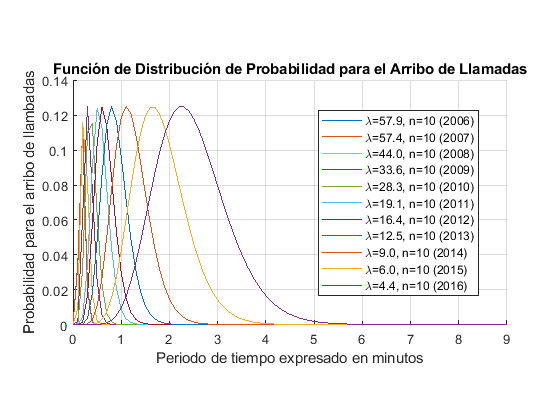

% Activamos la grilla
grid on
% Configuramos la relación de aspecto del grafico
pbaspect([16 9 1])
% Configuramos los detalles del grafico
title(['Función de Distribución de Probabilidad para el Arribo de Llamadas'])
xlabel('Periodo de tiempo expresado en minutos')
ylabel('Probabilidad para el arribo de llambadas')

% Definimos el intervalo de tiempo de observación en minutos
t=[0:.1:10];
% 
N=[1:1:10];
%
l=lamb(11);
% Configuramos la figura
figure
hold on
for n=1:length(N)
    p=poisspdf(n,l*t);
    plot(t,p)        
    % Construimos data para la leyenda
    data{n}=['\lambda='...
      num2str(l,'%2.2f')...
      ', n='...
      num2str(n,'%.0f')...
      ' ('...
      char(T.("Año")(11))...
      ')'];
end

% Configuramos la leyenda del grafico
legend(data,'Location','northeast','NumColumns',1)

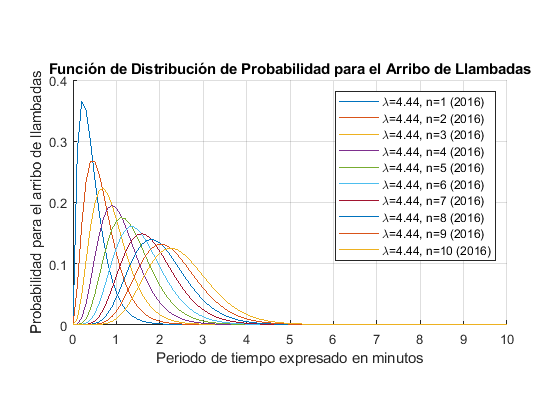

% Activamos la grilla
grid on
% Configuramos la relación de aspecto del grafico
pbaspect([16 9 1])
% Configuramos los detalles del grafico
title(['Función de Distribución de Probabilidad para el Arribo de Llambadas'])
xlabel('Periodo de tiempo expresado en minutos')
ylabel('Probabilidad para el arribo de llambadas')                   

## F. Trafico ofrecido en Erlangs

Esta definida por una distribucion del tipo exponecial

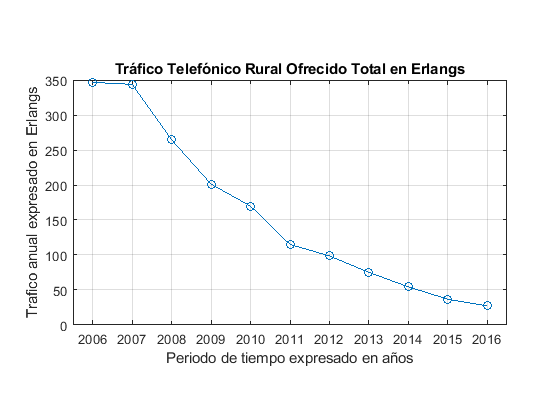

figure
A=T.TotalPeru./525600;
plot(T.("Año"),A,'-o')
grid on
pbaspect([16 9 1])
title('Tráfico Telefónico Rural Ofrecido Total en Erlangs')
xlabel('Periodo de tiempo expresado en años')
ylabel('Trafico anual expresado en Erlangs')

## F. Volumen de trafico en minutos y Tráfico ofrecido en Erlangs

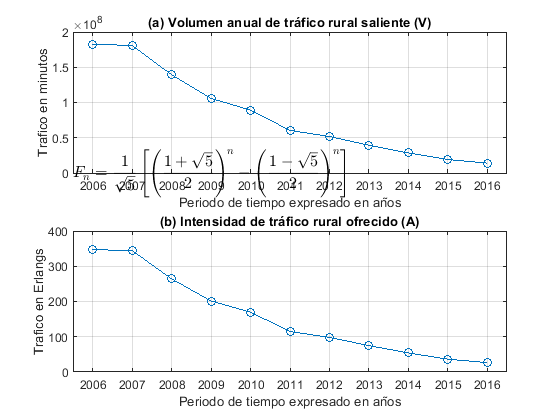

figure
subplot(2,1,1);
plot(T.("Año"),T.TotalPeru,'-o')
grid on
%pbaspect([16 9 1])
title('(a) Volumen anual de tráfico rural saliente (V)')
xlabel('Periodo de tiempo expresado en años')
ylabel('Trafico en minutos')

% Build a string that contains the Latex expression
eqtext = '$$F_n={1 \over \sqrt{5}}';
eqtext = [eqtext '\left[\left({1+\sqrt{5}\over 2}\right)^n -'];
eqtext = [eqtext '\left({1-\sqrt{5}\over 2}\right)^n\right]$$'];

% Add the string containing the Latex expression to the plot
text(0.5, 125, eqtext, 'Interpreter', 'Latex', 'FontSize', 12, 'Color', 'k')

subplot(2,1,2); 

% Convert categorical to double
anios=str2double(string(T.("Año")));
amins=365*ones(1,length(anios));
% Calculamos los años bisiestos
for i=[1:length(anios)]
    anio=anios(i);
    if(mod(anio,4)==0 && mod(anio,100)~=0)
        amins(i)=amins(i)+1;
    end
end
amins=24*60*amins';

A=T.TotalPeru./amins;
plot(T.("Año"),A,'-o')
grid on
%pbaspect([16 9 1])
title('(b) Intensidad de tráfico rural ofrecido (A)')
xlabel('Periodo de tiempo expresado en años')
ylabel('Trafico en Erlangs')

## G. Probabilidad de Arribos de Llamadas vs Tiempo y Lambda

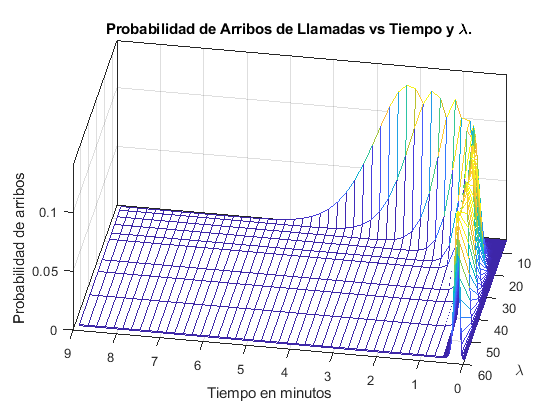


% Consideramos la tasa de duración de llambada mu=10. Es decir, el tiempo
% promedio de servicio 6 minutos
ts=6;
mu=ts^-1;

% Calculambos la tasa promedio de arribo de llambadas
lamb=mu.* T.TotalPeru./amins;

% Numero de arribos promedios en el tiempo
n=10;
% Definimos el intervalo de tiempo de observación en minutos
temp=horzcat([0:.010:.5], [.5:.2:9]);
% Generamos la matriz de tiempo
tiempo=[];
for i=1:length(lamb)
    tiempo=horzcat(tiempo,temp');
end
% Generamos la matriz de lamb
lambda=[];
for i=1:length(temp)
    lambda=vertcat(lambda,lamb');
end
% Generamos la probabilidad de arribos
prob=[];
for t=1:length(temp)
    for l=1:length(lamb)
        prob(t,l)=poisspdf(n,lambda(t,l)*tiempo(t,l));
    end
end

% Create the 3D plot
figure
%plot3(tiempo, lambda, prob)
mesh(tiempo, lambda, prob)
%surf(tiempo, lambda, prob)
%surfc(tiempo, lambda, prob)
box on

pbaspect([25 16 12])
view([-170 30])
%view([-15 30])
axis([0 9 4 60 0 .14])
%shading interp

% Add title and axis labels
xlabel('Tiempo en minutos')
ylabel('\lambda')
zlabel('Probabilidad de arribos')
title('Probabilidad de Arribos de Llamadas vs Tiempo y \lambda.')

## H. Probabilidad de Arribos de Llamadas vs Tiempo y Número de Arribos.

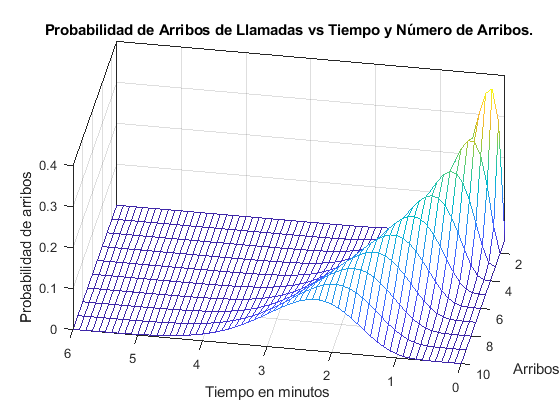


% Consideramos la tasa de duración de llambada mu=10. Es decir, el tiempo
% promedio de servicio 6 minutos
ts=6;
mu=ts^-1;
% Calculambos la tasa promedio de arribo de llambadas
lamb=mu.* T.TotalPeru./amins;

l=lamb(end);
% Numero de arribos promedios en el tiempo
nume=[1:1:10];
% Definimos el intervalo de tiempo de observación en minutos
temp=[0:.1:10];
% Generamos la matriz de tiempo
tiempo=[];
for i=1:length(nume)
    tiempo=horzcat(tiempo,temp');
end
% Generamos la matriz de numero de arribos
arribo=[];
for i=1:length(temp)
    arribo=vertcat(arribo,nume);
end
% Generamos la probabilidad de arribos
prob=[];
for t=1:length(temp)
    for n=1:length(nume)
        prob(t,n)=poisspdf(arribo(t,n),l*tiempo(t,n));
    end
end

% Create the 3D plot
figure
%plot3(tiempo, arribo, prob)
mesh(tiempo, arribo, prob)
%surf(tiempo, arribo, prob)
%surfc(tiempo, arribo, prob)
box on

pbaspect([25 16 12])
%view([190 10])
%view([-15 30])
view([-170 30])
axis([0 6 1 10 0 .4])
shading interp

% Add title and axis labels
xlabel('Tiempo en minutos')
ylabel('Arribos')
zlabel('Probabilidad de arribos')
title('Probabilidad de Arribos de Llamadas vs Tiempo y Número de Arribos.')

## I. Probabilidad de Arribos de Llamadas vs Lambda, Tiempo y Número de Arribos

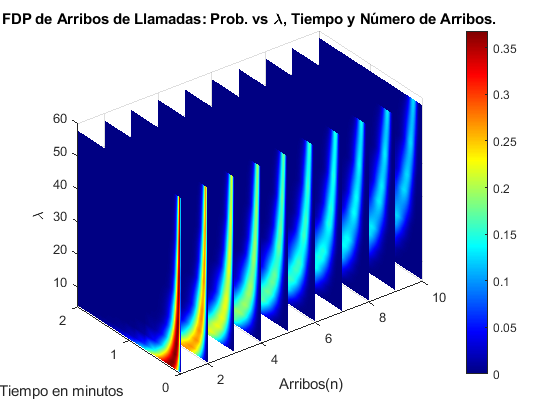


% Consideramos la tasa de duración de llambada mu=10. Es decir, el tiempo
% promedio de servicio 6 minutos
ts=6;
mu=ts^-1;
% Calculambos la tasa promedio de arribo de llambadas
lamb=mu.* T.TotalPeru./amins;
% Numero de arribos promedios en el tiempo
narr=[1:1:10];
% Definimos el intervalo de tiempo de observación en minutos
temp=horzcat([0:.010:.5], [.5:.2:10]);
% Generamos la matriz de tiempo
[tiempo,lambda,arribo]=meshgrid(temp,lamb,narr);

prob=poisspdf(arribo,lambda.*tiempo);
figure

for n=1:1:length(narr)
    %surf(tiempo(:,:,n),lambda(:,:,n),arribo(:,:,n),prob(:,:,n))
    %surf(tiempo(:,:,n),arribo(:,:,n),lambda(:,:,n),prob(:,:,n))    
    surf(arribo(:,:,n),tiempo(:,:,n),lambda(:,:,n),prob(:,:,n))
    %mesh(arribo(:,:,n),tiempo(:,:,n),lambda(:,:,n),prob(:,:,n))    
    hold on
end

xlabel('Arribos(n)')
ylabel('Tiempo en minutos')
zlabel('\lambda')
title('FDP de Arribos de Llamadas: Prob. vs \lambda, Tiempo y Número de Arribos.')

colormap jet
colorbar
shading interp

pbaspect([36 20 25])
axis([1 10 0 2 4 60])

hold off
grid on

## J. **FDP para el promedio de arribo de llamadas, con n constante**

figure

subplot(2,1,1); 
% Consideramos la tasa de duración de llambada mu=10. Es decir, el tiempo
% promedio de servicio 6 minutos
ts=6;
mu=ts^-1;

% Calculambos la tasa promedio de arribo de llambadas
lamb=mu.* T.TotalPeru./amins;

% Numero de arribos promedios en el tiempo
n=10;
% Definimos el intervalo de tiempo de observación en minutos
temp=horzcat([0:.010:.5], [.5:.2:9]);
% Generamos la matriz de tiempo
tiempo=[];
for i=1:length(lamb)
    tiempo=horzcat(tiempo,temp');
end
% Generamos la matriz de lamb
lambda=[];
for i=1:length(temp)
    lambda=vertcat(lambda,lamb');
end
% Generamos la probabilidad de arribos
prob=[];
for t=1:length(temp)
    for l=1:length(lamb)
        prob(t,l)=poisspdf(n,lambda(t,l)*tiempo(t,l));
    end
end

% Create the 3D plot
%figure
%plot3(tiempo, lambda, prob)
mesh(tiempo, lambda, prob)
%surf(tiempo, lambda, prob)
%surfc(tiempo, lambda, prob)
box on

%pbaspect([25 16 12])
view([-170 30])
%view([-15 30])
axis([0 9 4 60 0 .14])
%shading interp

% Add title and axis labels
xlabel('Tiempo en minutos')
ylabel('\lambda')
zlabel('Probabilidad')
title('FDP de Arribos de Llamadas: Prob. vs Tiempo y \lambda, con n=10 constante.')

subplot(2,1,2);

% Consideramos la tasa de duración de llambada mu=10. Es decir, el tiempo
% promedio de servicio 6 minutos
ts=6;
mu=ts^-1;

% Convert categorical to double
anios=str2double(string(T.("Año")));
amins=365*ones(1,length(anios));
% Calculamos los años bisiestos
for i=[1:length(anios)]
    anio=anios(i);
    if(mod(anio,4)==0 && mod(anio,100)~=0)
        amins(i)=amins(i)+1;
    end
end
amins=24*60*amins';

% Calculambos la tasa promedio de arribo de llambadas
lamb=mu.* T.TotalPeru./amins;

% Numero de arribos promedios en el tiempo
n=10;
% Definimos el intervalo de tiempo de observación en minutos
t=[0:.1:9];
% Configuramos la figura
%figure
hold on
for i=1:length(lamb)
    % Extraemos el lamb correspodiente por cada año
    l=lamb(i);
    
    p=poisspdf(n,l*t);
    
    %p=(exp(1).^(-l*t)).*((l*t).^n)./factorial(n); % equivalente
    % Construimos data para la leyenda
    plot(t,p)
    % Construimos data para la leyenda
    data{i}=['\lambda='...
      num2str(lamb(i),'%2.1f')...
      ' ('...
      char(T.("Año")(i))...
      ')'];
end
% Cambiando la direción del eje X
set(gca,'Xdir','reverse')
% Configuramos la leyenda del grafico
legend(data,'Location','best','NumColumns',2)

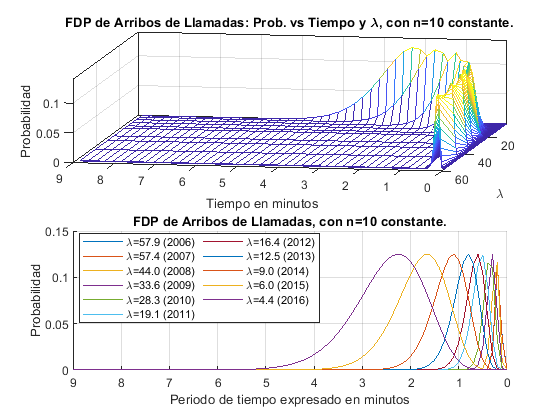

% Activamos la grilla
grid on
% Configuramos la relación de aspecto del grafico
%pbaspect([16 9 1])
% Configuramos los detalles del grafico
title(['FDP de Arribos de Llamadas, con n=10 constante.'])
xlabel('Periodo de tiempo expresado en minutos')
ylabel('Probabilidad')

## G. **FDP para el promedio de arribo de llamadas, con lambda constante**

figure
subplot(2,1,1); 
% Consideramos la tasa de duración de llambada mu=10. Es decir, el tiempo
% promedio de servicio 6 minutos
ts=6;
mu=ts^-1;
% Calculambos la tasa promedio de arribo de llambadas
lamb=mu.* T.TotalPeru./amins;

l=lamb(end);
% Numero de arribos promedios en el tiempo
nume=[1:1:10];
% Definimos el intervalo de tiempo de observación en minutos
temp=[0:.1:10];
% Generamos la matriz de tiempo
tiempo=[];
for i=1:length(nume)
    tiempo=horzcat(tiempo,temp');
end
% Generamos la matriz de numero de arribos
arribo=[];
for i=1:length(temp)
    arribo=vertcat(arribo,nume);
end
% Generamos la probabilidad de arribos
prob=[];
for t=1:length(temp)
    for n=1:length(nume)
        prob(t,n)=poisspdf(arribo(t,n),l*tiempo(t,n));
    end
end

% Create the 3D plot
%figure
%plot3(tiempo, arribo, prob)
mesh(tiempo, arribo, prob)
%surf(tiempo, arribo, prob)
%surfc(tiempo, arribo, prob)
box on

%pbaspect([25 16 12])
%view([190 10])
%view([-15 30])
view([-170 30])
axis([0 9 1 10 0 .4])
shading interp

% Add title and axis labels
xlabel('Tiempo en minutos')
ylabel('Arribos(n)')
zlabel('Probabilidad')
title('FDP de Arribos de Llamadas: Prob. vs Tiempo y Arribos, con \lambda=4.44 constante.')

subplot(2,1,2);
% Definimos el intervalo de tiempo de observación en minutos
t=[0:.1:9];
% 
N=[1:1:10];
%
l=lamb(11);
% Configuramos la figura
%figure
hold on
for n=1:length(N)
    p=poisspdf(n,l*t);
    plot(t,p)        
    % Construimos data para la leyenda
    data{n}=['n='...
      num2str(n,'%.0f')...
      ' ('...
      char(T.("Año")(11))...
      ')'];
end
% Cambiando la direción del eje X
set(gca,'Xdir','reverse')
% Configuramos la leyenda del grafico
legend(data,'Location','northwest','NumColumns',2)

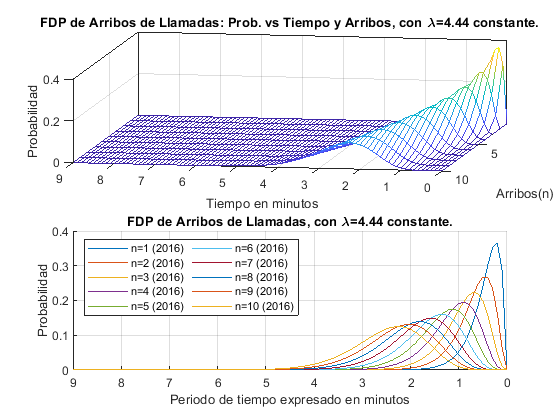

% Activamos la grilla
grid on
% Configuramos la relación de aspecto del grafico
%pbaspect([16 9 1])
% Configuramos los detalles del grafico
title(['FDP de Arribos de Llamadas, con \lambda=4.44 constante.'])
xlabel('Periodo de tiempo expresado en minutos')
ylabel('Probabilidad')